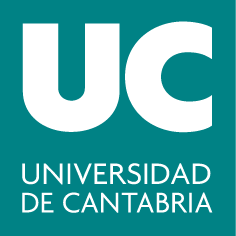

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **2. Números complejos**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Definición de números complejos

Ejecuta el siguiente código (Pulsa "Run Section"):

z = sqrt(-4)

MATLAB devolverá como resultado un número complejo.

La unidad imaginaria en MATLAB se representa mediante la variable `i` (o `j`). Por tanto, para definir el número complejo $2+3i$ bastaría con hacer lo siguiente:

% todas estas definiciones son equivalentes
z = 2+3i % recomendable
z = 2+3*i
z = 2+3j

MATLAB recomienda usar `1i` en lugar de `i` (como en la primera opción).

También podemos trabajar con números complejos expresados en forma exponencial:

Por ejemplo,

z = 2*exp(1i*pi/6)  % forma exponencial

### Operaciones con números complejos

En cualquier caso, podemos llevar a cabo las operaciones básicas (suma, producto, potenciación) mediante los operadores habituales:

z1 = 5-8j
z2 = exp(1i*pi/4)
suma = z1 + z2
resta = z1 - z2
prducto = z1*z2
potenciacion = z1^2

El comando `real` devuelve la parte real del número complejo, y el comando `imag` la parte imaginaria:

z = -6-4i
Rz = real(z)  % parte real de z
Iz = imag(z)  % parte imaginaria de z

Por su parte, `conj` devuelve el conjugado:

z = -3-9i
Cz = conj(z)  % conjugado de z

El comando `abs` permite obtener el valor absoluto de un número real o el módulo de un número complejo:

z = -5-2i
mz = abs(z)  % módulo de z

**Ejercicio: **Comprueba, para $$3+4i$$, que el producto de un número complejo por su correspondiente conjugado es igual al cuadrado del módulo:

% Escribe aquí el código:





Solución:

z = 3+4*1i;                          % definimos el número
z_conj = conj(z);                   % calculamos el conjugado
es_igual = (z*z_conj == abs(z)^2)   % comprobacion ( 1 - verdadero, 0 - falso)

El comando `angle` devuelve el argumento, expresado en radianes:

z = pi+i;
argumento = angle(z)  % argumento de z

Para pasar de radianes a grados se puede usar el comando `rad2deg`:

z = exp(1)-7i;
argumento = angle(z);  % argumento de z, en radianes
argumento_grados = rad2deg(angle(z))  % argumento de z, en grados

Todos los comandos vistos hasta el momento operan no sólo a nivel de un único número complejo, sino también sobre vectores (o matrices).

Ejercicio: Obtén la parte real, la imaginaria, el conjugado, el módulo y el argumento de los siguientes números complejos: $$2+i$, $\frac{1}{3} - 7i$ y $-6+4i$$

% Escribe aquí el código:





Solución:

% Creamos los números complejos:
z1 = 2+1i;
z2 = (1/3)-7i;
z3 = -6+4j;

% Los organizamos en un vector:
z = [z1, z2, z3];

% Calculamos:

Rz = real(z)  % parte real
Iz = imag([z1 z2 z3])  % parte imaginaria (sin crear el vector z)
Cz = conj(z)  % conjugado
Az = abs(z)  % modulo
Mz = angle(z)  % argumento

### **Graficado de números complejos**

El comando `compass` nos permite representar gráficamente un número complejo (o un vector de números complejos) en el plano complejo por medio de una flecha que tiene su origen en el punto $$(0,0)$$:

Por ejemplo,

compass(3+2j)
compass(3, 2)       % definicion equivalente a la anterior
compass([3+2j 1i])  % representar un vector de los números complejos

Se puede cambiar el color de la flecha fácilmente:

compass(3+2j, 'r')  % rojo
hold on
compass(3-2j, 'g')  % verde
hold off

Aquí, el comando` hold on` permite seguir dibujando en la misma ventana gráfica.

Para desactivar el efecto de `hold on `se utiliza el comando `hold off`.

Tabla de colores:

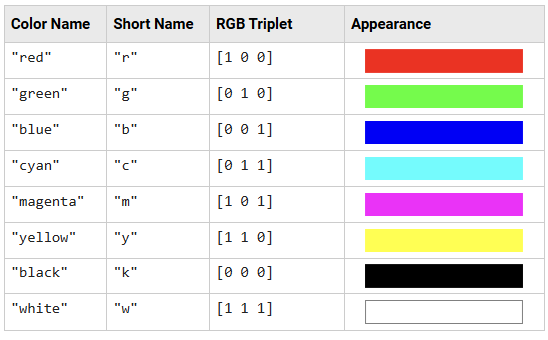

### Ejercicios propuestos

1. Dados$ $z=-1+2i$, $w=\sqrt{2}+3i$ y $s=-i$$, escribe en forma binómica los números complejos resutantes de las siguientes operaciones:

-  
$$$c_1 = \frac{1}{2}z-\frac{3}{5}\overline{w}Im(s)+szw$$$


- 
$$$c_2 = 2zw-s^{1023}z$$$


-  
$$$c_3 = s^{1023}+s^{1024}+s^{1025}+s^{1026}$$$


- 
$$$c_4 = \overline{zw} - \overline{z} \hspace{0.1cm} \overline{w}$$$


- 
$$$c_5 = \overline{z+w} - \overline{z} - \overline{w}$$$


% Escribe aquí el código:




Soluciones:

soluciones(1)

2.  Dados $$z_1 = 2-2i$ y $z_2 = \sqrt{2}e^{i\frac{\pi}{4}}$$:

- Comprueba que  $|z_1| = 2|z_2|$, $2\bar{z_2} =z_1$.

- Calcula el producto$ $z_1z_2$ $, calcula su parte real y comprueba que $Re(z_1 z_2) = z_1z_2$.

- Representa en un mismo gráfico $$z_1$$ (en azul) y $$z_2$$ (en rojo) sobre el plano complejo.

% Escribe aquí el código:







Soluciones:

soluciones(2)

### Resumen

**Definición de números complejos**

- Crear números complejos usando `i` o `j`.

- Forma exponencial: `exp(1i * argumento)`.

**Funciones específicas para números complejos **

- [`real`](https://es.mathworks.com/help/matlab/ref/real)**:** Obtener la parte real del número complejo.

- [`imag`](https://es.mathworks.com/help/matlab/ref/imag.html)**:** Obtener la parte imaginaria del número complejo.

- [`conj`](https://es.mathworks.com/help/matlab/ref/conj.html)**:** Obtener el conjugado de un número complejo.

- [`abs`](https://es.mathworks.com/help/matlab/ref/abs.html)**:** Obtener el módulo o valor absoluto de un número complejo.

- [`angle`](https://es.mathworks.com/help/matlab/ref/angle.html)**:** Obtener el argumento del número complejo en radianes.

**Graficado de Números Complejos**

- [`compass`](https://es.mathworks.com/help/matlab/ref/compass.html)**:** Representar números complejos en el plano complejo.

### Soluciones 

function [] = soluciones(n)
if n==1
    % Ejercicio 1:
    z = -1+2i;
    w = sqrt(2)+3i;
    s = -i;
    fprintf("Ejercicio 1:\n ");
    c1 = 0.5*z-0.6*conj(w)*imag(s)+s*z*w
    c2 = 2*z*w-s^1023*z
    c3 = s^1023+s^1024+s^1025+s^1026
    c4 = conj(z*w) - conj(z) * conj(w)
    c5 = conj(z+w) - conj(z) - conj(w)
else
    % Ejercicio 2:
    fprintf("Ejercicio 2:\n");
    z1 = 2-2i
    z2 = sqrt(2)*exp(1i*pi/4)
    Mz1 = abs(z1);
    Mz2 = abs(z2);
    Cz2 = 2*conj(z2);
    fprintf("Módulo de z1: %f,",Mz1)
    fprintf(" Módulo de z2: %f,\n",Mz2)
    fprintf("|z1| = 2|z2| = %f \n",(2*Mz2))
    fprintf("\n2conj(z2) = %f  %fi, que es z1\n",real(Cz2),imag(Cz2))
    producto = z1*z2;
    Reprod =real(producto);
    fprintf("Producto: z1 * z2 = %d, Re(z1*z2) = %d\n",producto, Reprod)
    compass(z1,'b')
    hold on
    compass(z2,'r')
end
end